# Synthesis of Pipes

Parameters

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Three_Pipes
r_sensor=2 mm
Q_inlet_CNN=5 uL/min
height_pipe=36 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s


w_1=w_Pipe_min;
Q=Q_inlet_CNN/3;

#### Péclet condition

Pe_cond=zeros(length(w_vec),length(l_vec));

for i_w=1:length(w_vec)

    %i_r/length(r_vec)*100

    for i_l=1:length(l_vec)

        %Hydraulic Resistance
        % R=12*mu*l_vec(i_l)/(1-0.63*height_pipe/w_vec(i_w))*1/(height_pipe^3*w_vec(i_w));
        
        %Volumetric flow
        % Q=p0/R;
        

        %Mean velocity
        %Circular channel of radius r_vec(i_r) [2, pag. 54]
        % v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l))
        %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
        v_char=Q/(w_vec(i_w)*height_pipe);

        %Peclet number, see [3, Eq. below 11] 
        Pe=v_char*height_pipe/D_coeff;

        %Evaluating the Effective Diffusion coefficient
        %Circular channel: [1, Eq.(4.54) pp.77]
        %D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
        %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
        %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
        % D_eff=D_coeff*(1+1/200*Pe^2);

        % %Péclet number, circular channel this evaluation follows [1,Eq. (4.44) pp.75]
        % Pe=r_vec(i_r)*v_char/D_coeff;
        
        %Validating the diffusion within the pipe
        %Diffusion occurred along the radial axis and x-axis
        if(Pe<4*l_vec(i_l)/height_pipe && Pe>1)
            Pe_cond(i_w,i_l)=1;

        %Diffusion hasn't occurred along the radial axis and x-axis
        elseif(Pe>4*l_vec(i_l)/height_pipe)
            Pe_cond(i_w,i_l)=0;
            %recording the lenght of the pipe
            if(i_w==1)
                l_vec_max_idx=i_l;
            end
            if(i_w==length(w_vec))
                l_vec_min_idx=i_l;
            end
        
        %Diffusion hasn't occurred along the axis
        elseif (Pe<1)
            Pe_cond(i_w,i_l)=-1;
        end
    end
end


## Plotting the Pe_cond matrix

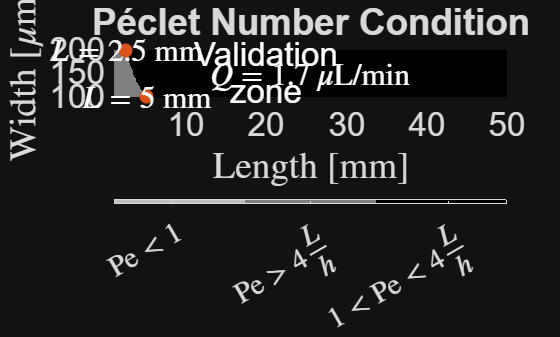

figure;

% Plot for all conditions in a single plot
hold on;
imagesc(l_vec*1e3, w_vec*1e6, Pe_cond); hold on
% colormap([0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.0072 0.4470 0.7410]); % Colors for 0, -1, and 1
colormap([0.75, 0.75, 0.75; 0.5, 0.5, 0.5; 0, 0, 0]); % Colors for 0, -1, and 1
caxis([-1 1]); % Set color axis limits to match Pe_cond values

text(20,150,{'Validation', 'zone'},'FontSize',fontsize,'Color','w','HorizontalAlignment','center');

text(l_vec(end/2)*1e3,w_vec(end/2)*1e6,{strcat('$Q=',num2str(Q*6e10,2),'\, \mu$L/min')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');

%lenght and width annotations
plot(l_vec(l_vec_max_idx)*1e3, w_vec(1)*1e6,'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);
plot(l_vec(l_vec_min_idx)*1e3, w_vec(end)*1e6,'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);
text(l_vec(l_vec_max_idx)*1e3,w_vec(1)*1e6,{strcat('$L=',num2str(l_vec(l_vec_max_idx)*1e3,2),' $ mm')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');
text(l_vec(l_vec_min_idx)*1e3,w_vec(end)*1e6,{strcat('$L=',num2str(l_vec(l_vec_min_idx)*1e3,2),'$ mm')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');

% Create a colorbar and set its ticks and labels
cb = colorbar('Ticks', [-0.7, 0, 0.7], 'TickLabels', {'$\mathrm{Pe}<1$', '$\mathrm{Pe}>4\frac{L}{h}$', '$1<\mathrm{Pe}<4\frac{L}{h}$'}, 'TickLabelInterpreter', 'latex', 'FontSize', fontsize-3,'Location','southoutside');
% cb.Layout.Tile='south';

% Set the color of the colorbar with transparency
%set(colorbarHandle, 'alpha', 0.5); % RGBA format, where A is the alpha value
%alpha(0.5);

xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(end)*1e3 w_vec(1)*1e6 w_vec(end)*1e6])
set(gca, 'YDir', 'normal');
title('Péclet Number Condition');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;


%Estimating the size of the pipes
L_1=16e-3;

V_sensor=pi*r_sensor^2*height_pipe;
w_Pipe_min=1.2*V_sensor/L_1/height_pipe;
V_Pipe_1=L_1*w_1*height_pipe;
V_sensor/V_Pipe_1/3*100

ans = 26.1799


disp(['w_Pipe_min=',num2str(w_Pipe_min*1e6),' um'])

w_Pipe_min=942.4778 um



w_Pipe_min=1e-3;
disp(['w_Pipe_min=',num2str(w_Pipe_min*1e3),' mm'])

w_Pipe_min=1 mm


### Synthesis of pipe and biffurcation

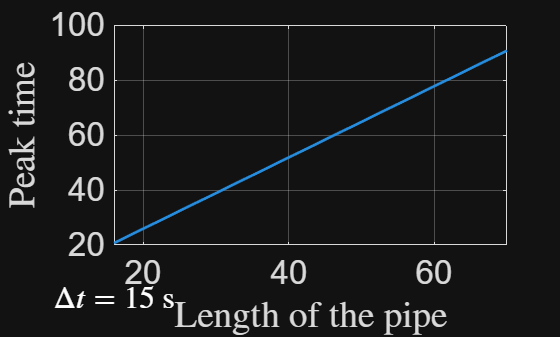

Q_min=inf;
Q_max=-inf;

syms t

%length of the pipe
total_points=1e2;
w_vec=linspace(100e-6,200e-6,total_points);%selected based on the mixer dimenssion in [4, Fig. 3]
l_vec=linspace(16,70,total_points)*1e-3;%selected based on the Peclet number condition

%defining the time interval
total_points_time=1e2;
t_ini=1e-7;
t_end=10;
t_vector = linspace(t_ini,t_end,total_points_time);
time_sampling=t_vector(2)-t_vector(1);

h_tau=zeros(1,length(l_vec));


% for i_w=1:length(w_vec)

    % i_w/length(w_vec)*100

    for i_l=1:length(l_vec)

        %Mean velocity
        %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
        v_char=Q/(w_Pipe_min*height_pipe);

        %Peclet number, see [3, Eq. below 11] 
        Pe=v_char*height_pipe/D_coeff;

        %Evaluating the Effective Diffusion coefficient
        %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
        %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
        D_eff=D_coeff*(1+1/200*Pe^2);      

        %Diffusion occurred along the radial axis and x-axis
        if(Pe<4*l_vec(i_l)/height_pipe && Pe>1)
            %Evaluating the peak time
            h_tau(i_l)=l_vec(i_l)/v_char-2*D_eff/v_char^2;


        %Diffusion hasn't occurred along the radial axis and x-axis
        elseif(Pe>4*l_vec(i_l)/height_pipe)
            disp(['Concentration is not constant along the x-axis, Pe=',num2str(double(Pe)),' is larger than ',num2str(4*l_vec(i_l)/height_pipe)])
                        i_l


        %Diffusion hasn't occurred along the axis
        elseif (Pe<1)
            disp(['Diffusion hasn''t occurred along the axis, Pe=',num2str(double(Pe)),' is less than ',num2str(sqrt(48))])
         
            i_l

        end
    end
% end

% Plotting the surface for the peak_tau matrix
figure;
plot(l_vec*1e3, h_tau,'LineWidth',2);hold on; grid on;
xlabel('Length of the pipe','Interpreter','latex');
ylabel('Peak time','Interpreter','latex');
%annotation for the sampling time
text(L_1*1e3,w_1*1e3,tau_sample,{strcat('$\Delta t=',num2str(tau_sample,2),'$ s')},'FontSize',fontsize-2,'Color','w','HorizontalAlignment','center',Interpreter='latex');
set(gca,'FontSize',fontsize);

### Length and width of the three pipes

Design withouth biffurcations

%find the coordinates for the tau sample
%Pipe 1
[~,idx]=min(abs(h_tau(:)-tau_sample));
% Get row and column from linear index
[row, col] = ind2sub(size(h_tau), idx);
L_1=l_vec(col)

L_1 = 0.0160


% R_1=12*mu*L_1/(1-0.63*height_pipe/w_1)*1/(height_pipe^3*w_1);
% Q_1=p0/R_1*6e10

%Pipe 2
[~,idx]=min(abs(h_tau(row,:)-2*tau_sample));
% Get row and column from linear index
% [~, col] = ind2sub(size(h_tau), idx);
L_2=l_vec(idx)

L_2 = 0.0231

w_2=w_Pipe_min;

%Pipe 3
[~,idx]=min(abs(h_tau(row,:)-3*tau_sample));
% Get row and column from linear index
% [~, col] = ind2sub(size(h_tau), idx);
L_3=l_vec(idx)

L_3 = 0.0345

w_3=w_Pipe_min;

#### Second method to calculate the lengths

**Description**: This process assumes that all pipes has the same width $w$ and exploits the approximate relation between length of the pipes and peak time as

$t_\text{peak}=\frac{L}{v_\text{char}}-\frac{2D_\text{eff}}{v^2_\text{char}}$ (1)

where $D_\text{eff}$ is the effective diffusion coefficient given by [1, Eq. (4.54) pp. 77]

$D_\text{eff}=D_\text{coeff}\left(1+\frac{1}{200}\text{Pe}^2\right)$,  (2)

$v_\text{char}$ is the characteristic speed, here evalueated as the average speed within the microfluidic pipe as [1, below Eq. (3.40) pag. 53]

$v_\text{char}=\frac{Q}{w\times \text{height pipe}}$, (3)

and $\text{Pe}$ is the Peclet number evaluated as [3, Eq. below 11]

$\text{Pe}=\frac{v_\text{char}\times \text{height pipe}}{D_\text{coeff}}$ (4)

The method followed in this code aims to synthetize each pipe, evaluating its length $L_i$, in an iterative manner. On each $k$-th iteration the length of each pipe of index $i$ is evaluted with Eq. (1) as follows

         1. Evaluate an initial guess for each length $L^{(1)}_i$. This is accomplished by assuming the volumetric pipe per flow is $Q_i=\frac{1}{3}Q_\text{inlet}$ and       evaluating each length using Eq. (1) as 

                    $L^{(k)}_i \leftarrow v_{\text{char},i}\,t_i+\frac{2D_{\text{eff},i}}{v_{\text{char},i}}$,  (5)

        2. With the evaluated lengths, update the new values for $Q_i$ as follows from the relation

                    $Q_i=Q_\text{tot}\frac{\frac{1}{L_i}}{\sum_{k=1}^3{\frac{1}{L_k}}}$ (6)

        3. Evaluate the peak time per pipe using Eq. (1) and the updated values for the volumetric flows in Eq. (6).

        4. Iterate to Step 1 whenever the relative error mets a design criteria $\frac{\text{max}|L^{(k)}_i-L^{(k-1)}_i|}{L^{(k-1)}}<\text{margin}$

%Target peak time
t_target = [1; 2; 3]*tau_sample;   % [t1; t2; t3]
%Fixed cross-sectional area
A = w_1*height_pipe;

%% Initial guess for lengths (use your old design or something reasonable)
% Example guess: proportional to sqrt(t) scaled to something:
L_0 = [L_1 L_2 L_3]';   % meters, e.g. ~2 cm baseline. Replace with yours.

%% Iteration settings
maxIter = 200;
lambda = 0.4;          % relaxation (0.2 to 0.8 typically robust)
tol = 1e-6;

L=[];
L(:,1)=L_0;

relchg=[];

for it = 1:maxIter

    % Flow split for 3 parallel branches with R_i ∝ L_i
    invL = 1./L;
    Qi = Q_inlet_CNN * (invL / sum(invL));     % 3x1

    % Velocities
    vi = Qi / A;

    % Effective diffusivity per branch
    Pe = (vi*height_pipe) / D_coeff;
    Deff = D_coeff .* (1 + (Pe.^2)/200);

    % Fixed-point update for lengths
    Lnew_raw = vi .* t_target + (2*Deff) ./ vi;

    % Relaxation
    Lnew = (1-lambda)*L(:,it) + lambda*Lnew_raw;

    % Convergence check
    relchg(it) = max(abs(Lnew - L(:,it)) ./ max(L(:,it), 1e-12));
    L(:,it+1) = Lnew;

    if relchg < tol
        fprintf('Converged in %d iterations (relchg=%.3e)\n', it, relchg);
        break
    end
end

% Report
invL = 1./L;
Qi = Q_inlet_CNN * (invL / sum(invL));
vi = Qi / A;
Pe = (vi*height_pipe) / D_coeff;
Deff = D_coeff .* (1 + (Pe.^2)/200);

t_pred = L./vi - 2*Deff./(vi.^2);

disp(table((1:3)', L(:,it+1), Qi, vi, Pe, Deff, t_pred(:,it+1), t_target, ...
    'VariableNames', {'branch','L_m','Q_m3s','v_ms','Pe','Deff_m2s','t_pred_s','t_target_s'}));

    branch      L_m         Q_m3s          v_ms         Pe       Deff_m2s     t_pred_s    t_target_s
    ______    ________    __________    __________    ______    __________    ________    __________

      1       0.015223    3.6468e-11      0.001013    74.425    1.4061e-08       15           15    
      2       0.021519    2.5798e-11    0.00071661    52.649    7.2813e-09       30           30    
      3       0.026351    2.1067e-11     0.0005852    42.994    5.0188e-09       45           45    



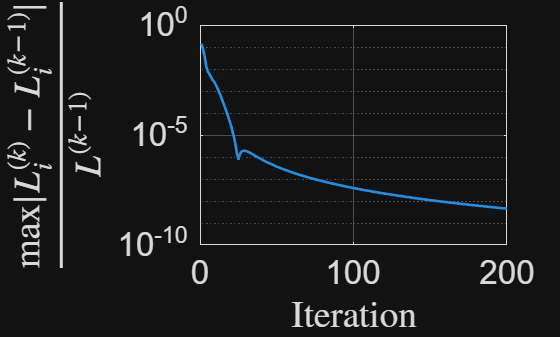


figure;
semilogy(1:it,relchg,'LineWidth',2); grid on;
xlabel('Iteration','Interpreter','latex');
ylabel('$\frac{\mathrm{{max}}|L^{(k)}_i-L^{(k-1)}_i|}{L^{(k-1)}}$','Interpreter','latex');
set(gca,'FontSize',fontsize);


%Assigning the evaluated lengths to the pipe lengths

L_1=L(1,it+1);
L_2=L(2,it+1);
L_3=L(3,it+1);

%Calculations of the Volume
V_CNN=(L_1+L_2+L_3)*w_1*height_pipe;
V_sensor=pi*r_sensor^2*height_pipe;
disp(['V_sensor/V_CNN =',num2str(V_sensor/V_CNN*100),' %'])

V_sensor/V_CNN =19.9173 %



%Storing
Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, L_1, "m", "Length of Pipe_1");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, w_1, "m", "Width of Pipe 1");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, L_2, "m", "Length of Pipe_2");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, w_2, "m", "Width of Pipe 2");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, L_3, "m", "Length of Pipe_3");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, w_3, "m", "Width of Pipe 3");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

%Theoretical Evaluations
%Pipe 1
%Flow to the pipe 1 in a single connection
%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q/(w_1*height_pipe)

v_char = 7.7160e-04

%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff

Pe = 56.6893

%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2)

D_eff = 8.3635e-09

time=0:time_delta:time_simul*3;
%Evaluating the concentration of the straigth channel
conc_Pipe_1_Theo=1./2.*erfc((L_1-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_1_Theo=gradient(conc_Pipe_1_Theo,time);
%Approximated Peak time
peak_time=L_1/v_char-2*D_eff/v_char^2;

%Pipe 2
%Flow to the pipe 1 in a single connection
%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q/(w_2*height_pipe)

v_char = 7.7160e-04

%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff

Pe = 56.6893

%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2)

D_eff = 8.3635e-09

%Evaluating the concentration of the straigth channel
conc_Pipe_2_Theo=1./2.*erfc((L_2-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_2_Theo=gradient(conc_Pipe_2_Theo,time);
%Approximated Peak time
peak_time_2=L_2/v_char-2*D_eff/v_char^2;

%Pipe 3
%Flow to the pipe 1 in a single connection
%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q/(w_3*height_pipe)

v_char = 7.7160e-04

%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff

Pe = 56.6893

%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2)

D_eff = 8.3635e-09

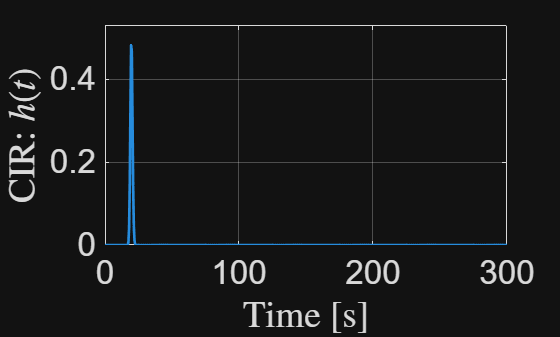

%Evaluating the concentration of the straigth channel
conc_Pipe_3_Theo=1./2.*erfc((L_3-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_3_Theo=gradient(conc_Pipe_3_Theo,time);
%Approximated Peak time
peak_time_3=L_3/v_char-2*D_eff/v_char^2;

figure;
plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
% plot(time,h_cir_2_Theo,'LineWidth',2);
% plot(time,h_cir_3_Theo,'LineWidth',2);

% plot(peak_time,h_cir_1_Theo(round(peak_time/time_delta)),'ow','LineWidth',2,'MarkerSize',10);
% plot(peak_time_2,h_cir_2_Theo(round(peak_time_2/time_delta)),'ow','LineWidth',2,'MarkerSize',10);
% plot(peak_time_3,h_cir_3_Theo(round(peak_time_3/time_delta)),'ow','LineWidth',2,'MarkerSize',10);

xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
set(gca,'FontSize',fontsize);
% legend({'Pipe 1','Pipe 2','Pipe 3','Peak approximation'},'Location','northeast');
axis([0 time(end) 0 1.1*max(h_cir_1_Theo)]);

# CAD design of the CNN-like structure

**Description:** This code evaluates the coordinates for the upper lines and lower lines for each pipe. As represented on Fig. 1, we define each pipe coordinates with points.

## Center shape

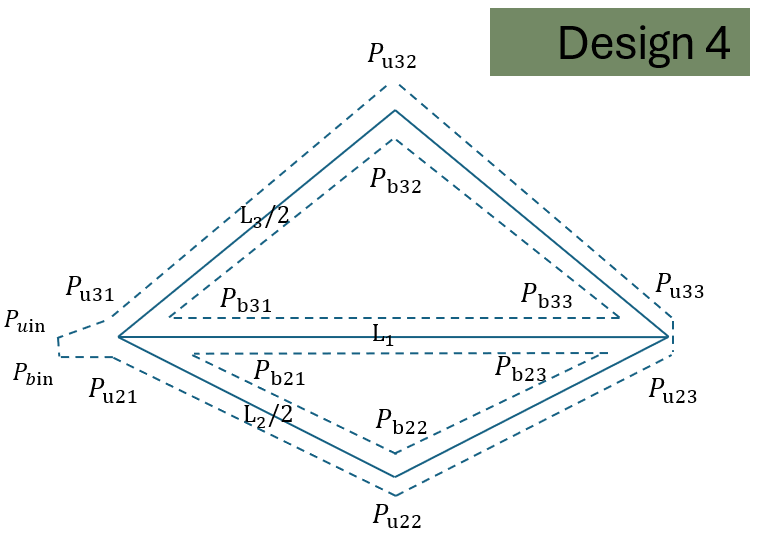

Figure 1: Reference points on the design.

### Inlet dimensions

%this reference coordinates are coming from the original CAD desing. This
%two points reference refer to the pipe just after the mixer on the
%transmitter side. See Fig. 1.
% P_u0=[-42.36063776 1.75826183]*1e-3;
% P_b0=[-42.36063776 1.65926683]*1e-3;
%width for the mixer pipe, this is taken from [4]
% w_0=P_u0(2)-P_b0(2);
w_0=98.995*1e-6;%measured with the design COMSOL_3D_CNN_Design_1_2.mph, placed at \COMSOL_CNN_height_38um_Q_2_2_uL_tetrazine_Design_1\CAD_design
fprintf('w_0=%.8f um', w_0*1e6);   % fixed-point with 15 decimals

w_0=98.99500000 um

%length of the inlet
L_0=210e-6;
fprintf('L_0=%.8f mm', L_0*1e3);   % fixed-point with 15 decimals

L_0=0.21000000 mm

### Center coordinates for the two top and bottom triangles in Figure 2

% basic validity checks (optional)
if L_3 < L_1 || L_2 < L_1
    error('Need L2 >= L1 and L3 >= L1 to form valid isosceles triangles.');
end

% base endpoints
Pc31 = [0, 0];
Pc33 = [L_1, 0];

% heights of upper and lower triangles
h_3 = sqrt( (L_3/2)^2 - (L_1/2)^2 );
h_2 = sqrt( (L_2/2)^2 - (L_1/2)^2 );

% height of upper triangle
Pc32 = [L_1/2,  h_3];

% height of lower triangle
Pc22 = [L_1/2, -h_2];

% Pc11

%Center polygon
% % Stack all vertices row by row
% coords = [Pc31; Pc32; Pc33; Pc22; Pc31; Pc33];
% %saving in the CSV file
% outputFile = fullfile(pwd, 'dataset', 'polygon_center.csv'); % build full path safely
% writematrix(coords, outputFile);

#### Upper polygon

% Inner triangle vertices

% Pb32: intersection of the two offset slanted sides
x_b32 = L_1/2;
y_b32 = h_3 - (w_3 * L_3) / (2 * L_1);
Pb32  = [x_b32,  y_b32];

% Pb31: left bottom vertex (offset left side & y = w_1/2)
x_b31 = (L_3 * w_3 + L_1 * w_1) / (4 * h_3);
y_b31 =  w_1 / 2;
Pb31  = [x_b31,  y_b31];

% Pb33: right bottom vertex (offset right side & y = w_1/2)
x_b33 = L_1 - x_b31;
y_b33 =  w_1 / 2;
Pb33  = [x_b33,  y_b33];

%Upper polygon
% Stack all vertices row by row
coords = [Pb31; Pb32; Pb33; Pb31];
%saving in the CSV file
outputFile = fullfile(pwd, 'datasets', 'polygon_upper_Phase_1.csv'); % build full path safely
writematrix(coords, outputFile);


#### Bottom Polygon

% height of lower outer triangle
h_2 = sqrt( (L_2/2)^2 - (L_1/2)^2 );

% ---- inner lower triangle vertices ----

% Pb21: left top vertex (offset left side & y = -w_1/2)
x_b21 = (L_2 * w_2 + L_1 * w_1) / (4 * h_2);
y_b21 = -w_1 / 2;
Pb21  = [x_b21, y_b21];

% Pb22: apex of inner lower triangle
x_b22 = L_1 / 2;
y_b22 = -h_2 + (L_2 * w_2) / (2 * L_1);
Pb22  = [x_b22, y_b22];

% Pb23: right top vertex (offset right side & y = -w_1/2)
x_b23 = L_1 - x_b21;
y_b23 = -w_1 / 2;
Pb23  = [x_b23, y_b23];

%Bottom polygon 
% Stack all vertices row by row
coords = [Pb21; Pb22; Pb23; Pb21];
%saving in the CSV file
outputFile = fullfile(pwd, 'datasets', 'polygon_bottom_Phase_1.csv'); % build full path safely
writematrix(coords, outputFile);



#### Outer polygon

% Pu32
Pu32 = [L_1/2, h_3 + (w_3 * L_3) / (2 * L_1)];
% Pu311
Pu311 = [0, (w_3 * L_3) / (2 * L_1)];
% Pu333
Pu333 = [L_1,  (w_3 * L_3) / (2 * L_1)];
% Pu22
Pu22 = [L_1/2, -h_2 - (w_2 * L_2) / (2 * L_1)];
% Pu211
Pu211 = [0, - (w_2 * L_2) / (2 * L_1)];


% Pu31
Pu311_x=Pu311(1)+(w_1/2-Pu311(2))*(Pu32(1)-Pu311(1))/(Pu32(2)-Pu311(2))

Pu311_x = -2.5869e-04

Pu31=[Pu311_x , w_1/2];
% Pu21
Pu21=[Pu311_x , -w_1/2];
% Pu33
Pu333_x=Pu333(1)+(w_1/2-Pu333(2))*(Pu32(1)-Pu333(1))/(Pu32(2)-Pu333(2))

Pu333_x = 0.0155

Pu33=[Pu333_x , w_1/2];
% Pu23
Pu23=[Pu333_x , -w_1/2];

%P_bin
Pbin=[-L_0/2,-w_0/2];
%P_uin
Puin=[-L_0/2,w_0/2];


%Outer polygon 
% Stack all vertices row by row
coords = [Pu31; Pu32; Pu33; Pu23; Pu22; Pu21; Pu31];
%saving in the CSV file
outputFile = fullfile(pwd, 'datasets', 'polygon_outer_Phase_1.csv'); % build full path safely
writematrix(coords, outputFile);

Pu23_x=Pu23(1);
Pu23_y=Pu23(2);

Pu33_x=Pu33(1);
Pu33_y=Pu33(2);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pu23_x, "m", "Width of Pipe 1");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pu23_y, "m", "Width of Pipe 1");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pu33_x, "m", "Width of Pipe 1");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

Table_param_COMSOL = upsertParamFromVar(Table_param_COMSOL, Pu33_y, "m", "Width of Pipe 1");
outFile = fullfile("datasets", "parameters_2D.csv");
writeComsolParamCSV(outFile, Table_param_COMSOL);

%===============Helpers========================

function writeComsolParamCSV(filename, T)
    % Writes the 3-column cell array back to CSV
    writetable(T, filename, "Delimiter", ",","WriteVariableNames", false);
end


function T = upsertParamFromVar(T, var, unit, desc)
%UPSERTPARAMFROMVAR Upsert a COMSOL parameter row using MATLAB variable name.
%
% Usage:
%   T = upsertParamFromVar(T, myVar, "mol/m^3", "Description");
%   T = upsertParamFromVar(T, myVar, "",        "Description");  % no unit

    name = inputname(2);
    if isempty(name)
        error("upsertParamFromVar: Could not infer variable name. Use upsertParamTable with explicit name.");
    end

    % If unit is omitted or passed as empty, treat as no-unit
    if nargin < 3 || isempty(unit) || (isstring(unit) && strlength(unit)==0) || ...
                     (ischar(unit) && strlength(string(unit))==0)
        unit = "";
    end

    % Desc can be omitted too
    if nargin < 4 || isempty(desc)
        desc = "";
    end

    T = upsertParamTable(T, string(name), var, unit, desc);
end


function T = upsertParamTable(T, name, value, unit, desc)
%UPSERTPARAMTABLE Insert or overwrite a parameter row (name, expr, desc)
% in a 3-column table T.

    name = string(name);

    % Normalize unit/desc robustly
    unit = normalizeTextScalar(unit);
    desc = normalizeTextScalar(desc);

    expr = buildComsolExpr(value, unit);

    % Find existing entry in first column
    idx = find(string(T{:,1}) == name, 1, "first");

    if isempty(idx)
        % Append new row (assign all columns)
        newRow = {name, expr, desc};
        T = [T; cell2table(newRow, "VariableNames", T.Properties.VariableNames)];
    else
        % Overwrite existing row
        T{idx,1} = name;
        T{idx,2} = expr;
        T{idx,3} = desc;
    end
end


function expr = buildComsolExpr(value, unit)
%BUILDCOMSOLPR Build "value[unit]" or "value" if unit is empty.

    unit = normalizeTextScalar(unit); % ensures "" if empty/whitespace/etc.

    if isnumeric(value)
        if ~isscalar(value)
            error("buildComsolExpr: value must be scalar for COMSOL parameters.");
        end
        valStr = string(num2str(value, "%.15g"));
    else
        valStr = string(value); % keep expressions as text
    end

    if strlength(unit) == 0
        expr = valStr;
    else
        expr = valStr + "[" + unit + "]";
    end
end


function s = normalizeTextScalar(x)
%NORMALIZETEXTSCALAR Convert x to a clean string scalar.
% - [] / missing / whitespace-only -> ""
% - char/string -> trimmed string scalar

    if nargin == 0 || isempty(x)
        s = "";
        return;
    end

    % Handle missing string
    if isstring(x) && isscalar(x) && ismissing(x)
        s = "";
        return;
    end

    s = string(x);
    if numel(s) ~= 1
        error("Expected a single unit/description text value, got %d elements.", numel(s));
    end

    s = strtrim(s);
    if ismissing(s)
        s = "";
    end
end


### References

[1] H. Bruus, Theoretical Microfluidics. 2008. doi: 10.1093/oso/9780199235087.001.0001.  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, "Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section," Mathematical and Computer Modelling, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: 10.1016/j.mcm.2006.11.029. 

[4] Murat paper